activecontourSegmentationTest

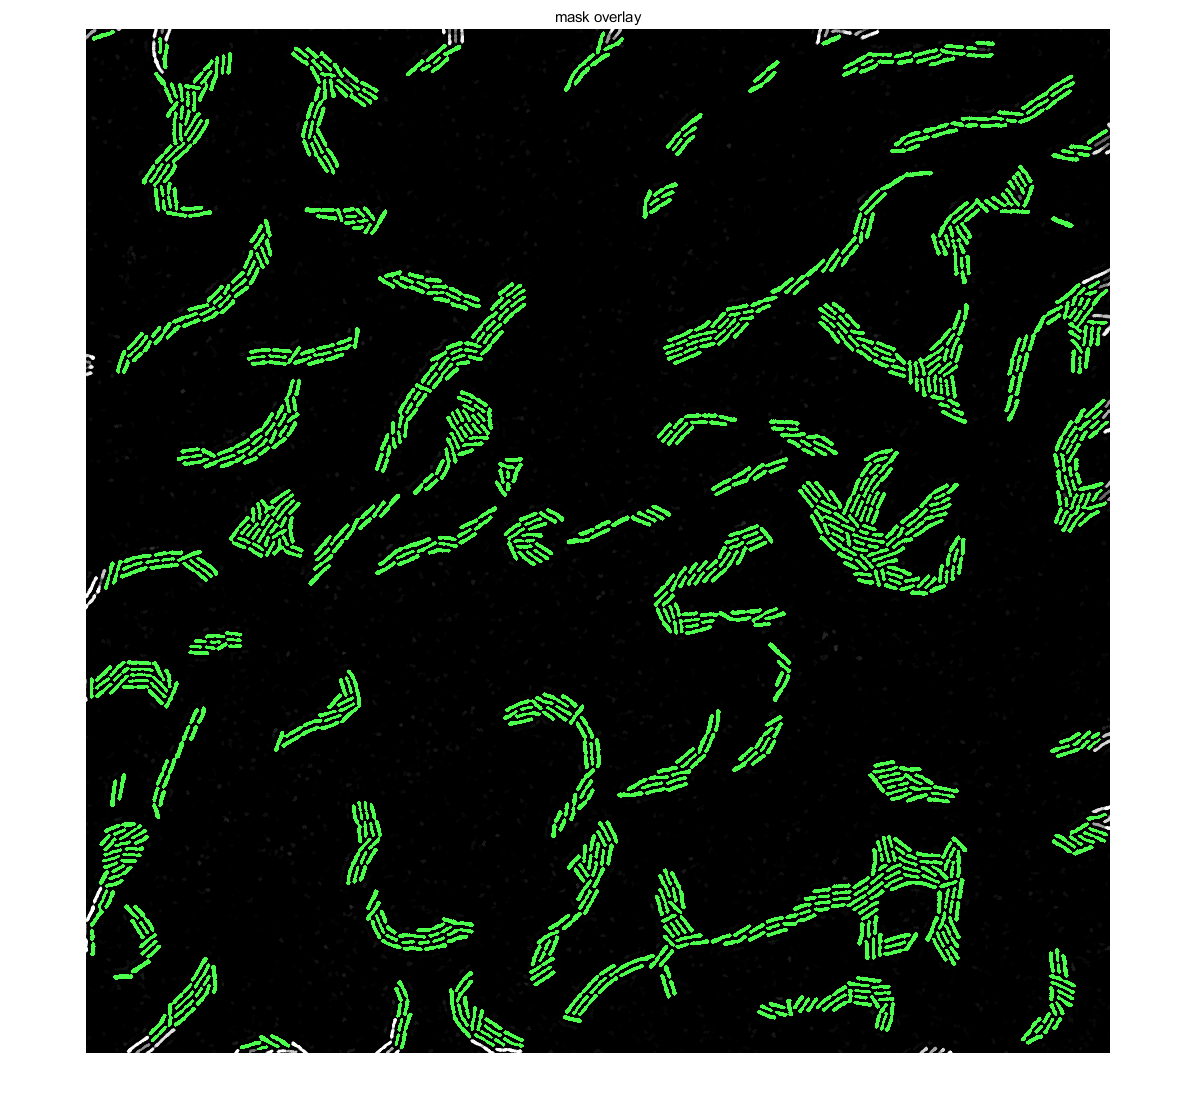

% image=import_tiff_stack('E:\2019-12-26 PAO1_deltpslpelfliC_IP32_100x ys\field0004\BF\imageBF04000.tif');
I=image;
% se = strel('disk',2);
% Io = imopen(I,se);
% imshow(I), title('Original Image')
% imshow(Io),title('Opening I-Io')
% 
% Ie = imerode(Io,strel('disk',3));
% imshow(Ie), title('Eroded image I-Ie ')
% Iobr = imreconstruct(Ie,Io);
% imshow(Iobr),title('Opening-by-Reconstruction I-Ie-Iobr ')
% 
% % [bw,~]=myImageProcessing_cBFys(Iobr,'w');
% % parameter
% % % grayThresh=40;
% % % areaThreshold=100;  % proper 60, overlap 60+40
% % % maxIntensity=45;
overlay = imoverlay(Iobr, bw, [.3 1 .3]);
imshow(overlay), title('mask overlay')

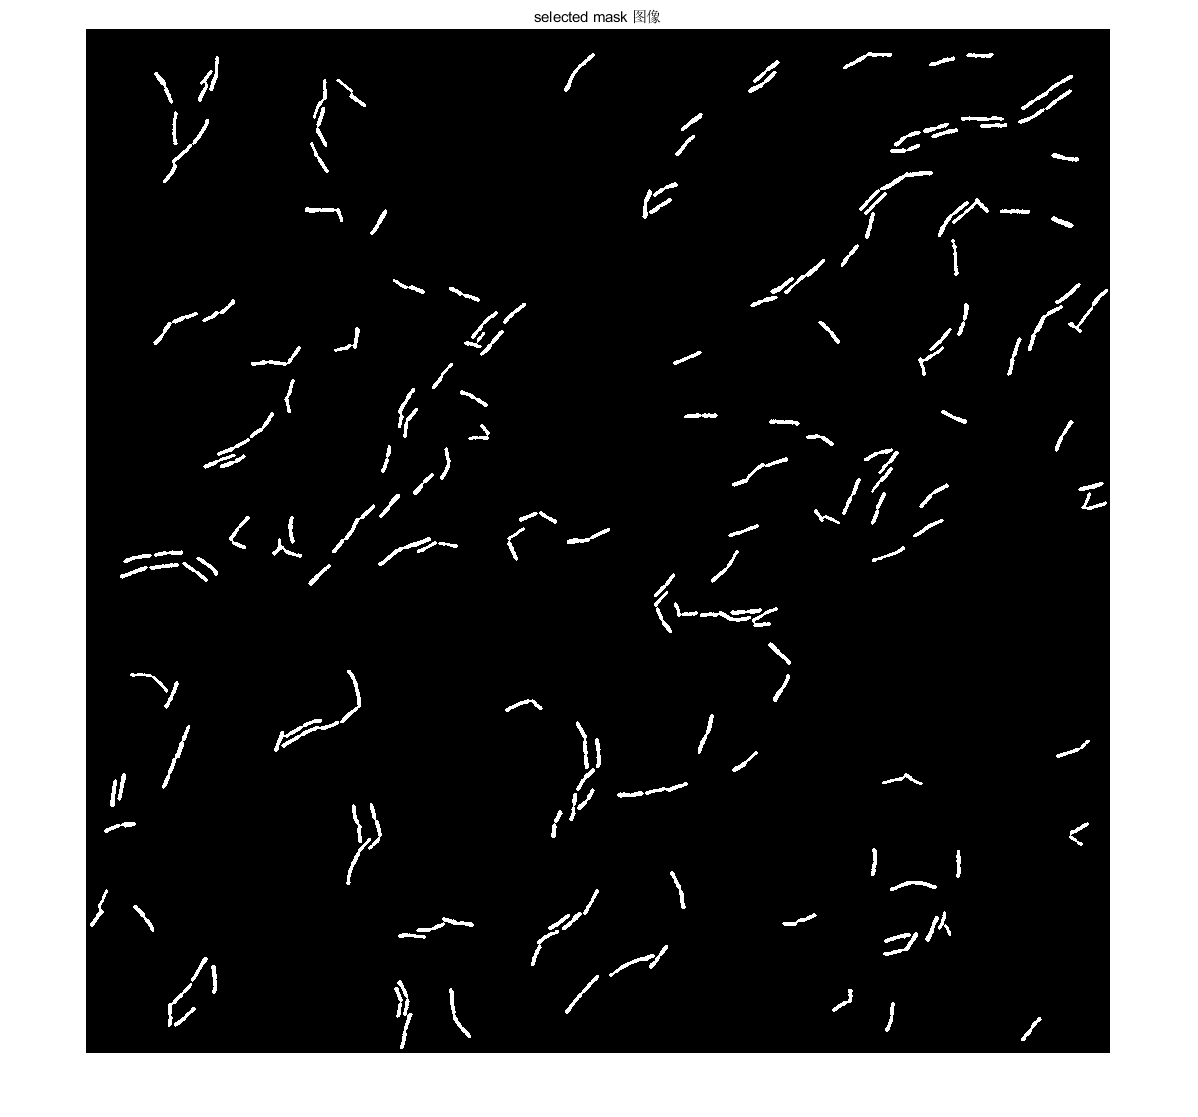


selctBw=false(size(bw));
stats = regionprops(bw,'PixelIdxList','PixelList');
for i=1:numel(stats)
    if numel(stats(i).PixelIdxList)>=400
        selctBw(stats(i).PixelIdxList)=1;
    end
end
imshow(selctBw),title('selected mask 图像')

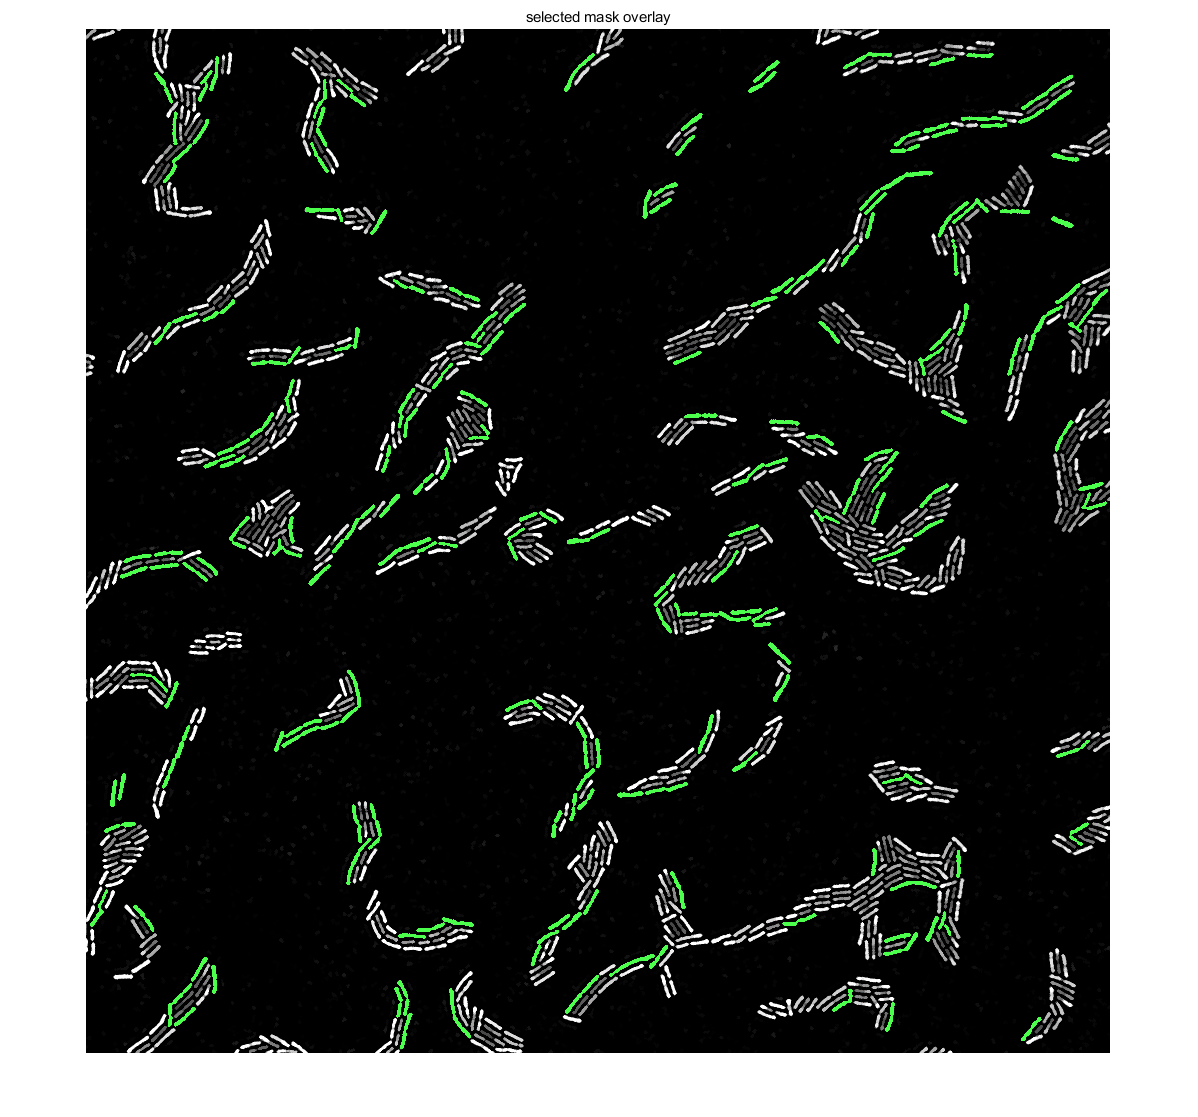


overlay1 = imoverlay(Iobr, selctBw, [.3 1 .3]);
imshow(overlay1), title('selected mask overlay')

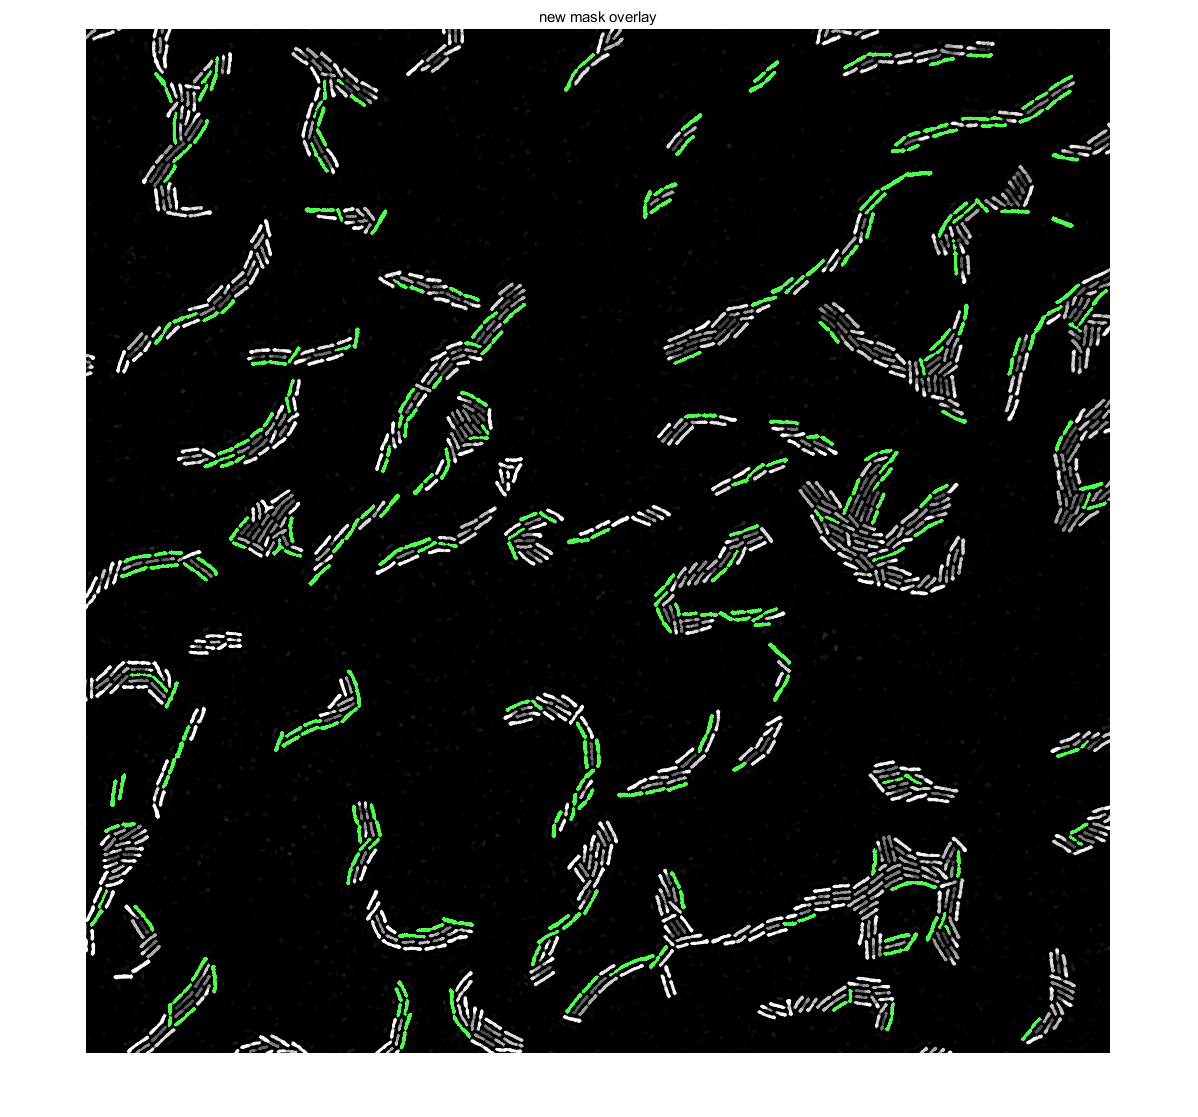


V = imadjust(Iobr,[0.1 1],[0,1],0.6);
selctBwNew = activecontour(V,selctBw,100);

overlay2 = imoverlay(Iobr, selctBwNew, [.3 1 .3]);
imshow(overlay2), title('new mask overlay')


% Ergb = label2rgb(E,'jet','w','shuffle');
% Ergb = label2rgb(E,'jet','w');
% figure,imshow(Ergb)